# Homework 01 - Analog Signal Acquisition and Conditioning

Please add your name, section, and semester information to the fields below

StudentName = ""; % First Last
Section = ""; % ex. A01
Semester = ""; % ex. Fall 2023

## Background

For this lab block you will be investigating the acquisition and conditioning of analog signals. You will use an oscilloscope built into the National Instruments ELVIS III Engineering Lab Workstation to measure a proposed signal conditioning circuit and determine if it meets a clients specifications for an application. This homework will review some of the basic concepts of analog signal acquisition from ECE 3741 and plotting using MATLAB.

The Signal Acquisition example below was simulated using the digital oscilloscope application you will use in lab. You may find it helpful to simulate the signal yourself for completing the questions below by going to [https://measurementslive.ni.com/](https://measurementslive.ni.com/) and selecting Device Simulation and then Oscilloscope & Function and Arbitrary Waveform Generator with the function generator settings:

- Waveform: Sine

- Frequency: 250 Hz

- Amplitude: 1.75 Vpp

- DC offset: -7.5 V

- Phase: 0°

## Signal Acquisition

Below is a picture of the oscilloscope module you will be using to acquire analog signals. Currently the signal being measured by the oscilloscope on Channel 1 is not visible on the screen and it is incapable of making accurate measurements of the signal properties. The best practice is to adjust the oscilloscope setting such that the signal is displayed such that the divisions being displayed on the screen can be used to determine the signal properties. The measurements calculated by the oscilloscope should then be an accurate representation of the signal.

### 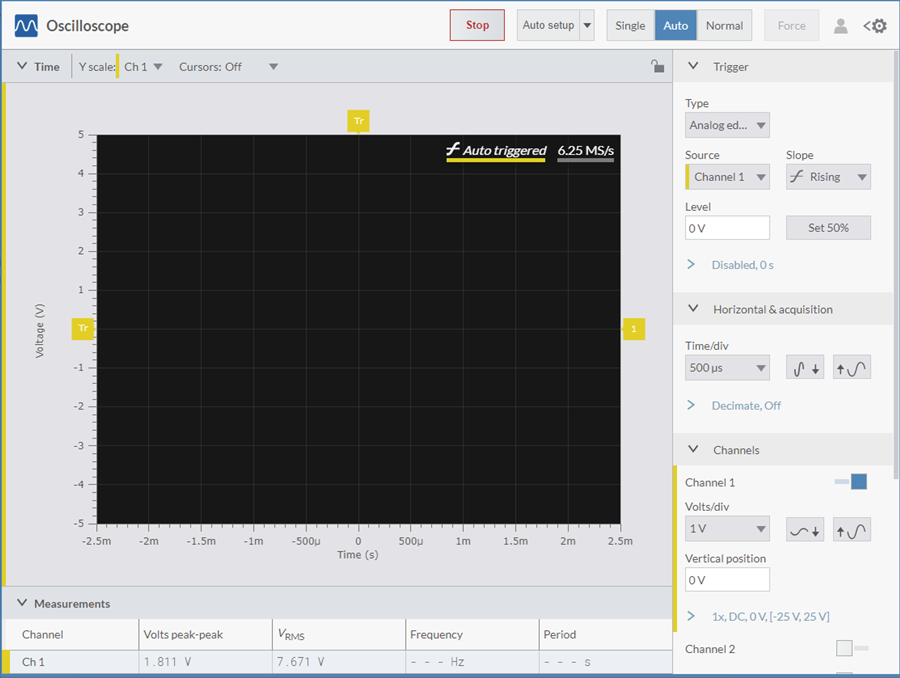

### Divisions

In oscilloscope terminology, a Division (div) is a vertical or horizontal tick mark. For example, on the oscilloscope above, the Timebase (Time/div) is set to 500 microseconds. That means each vertical line denotes 5 µs. Horizontal lines denote voltage levels (Volts/div), which is currently set to 1 Volts/div. We can adjust settings on the oscilloscope so that our signals can be clearly analyzed.

#### Problem 1

You want to adjust the screen setting so that the signal is visible. What setting should you adjust on the oscilloscope settings?

- Vertical Offset (V)

- Trigger Settings

- Timebase (Time/div)

- Voltage Scale (Volts/div)

- Cursor Settings

Problem_1_Answer = "-" % Select answer from list

#### Problem 2

Should you increase or decrease this setting?

- Increase

- Decrease

Problem_2_Answer = "-" % Select answer from list

After changing the oscilloscope settings, the signal on the screen is now visible, as shown below. However, the oscilloscope is still unable to calculate the signal properties.

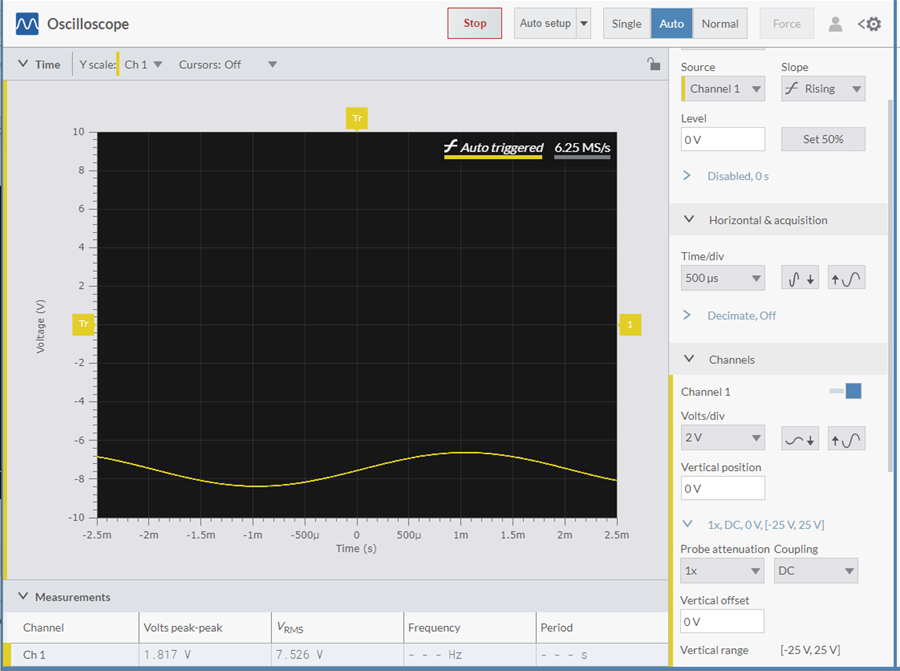

#### Problem 3

You want to move the signal so that it is centered around the x-axis. What setting do you adjust?

- Vertical Offset (V)

- Trigger Settings

- Timebase (Time/div)

- Voltage Scale (Volts/div)

- Cursor Settings

Problem_3_Answer = "-" % Select answer from list

#### Problem 4

Should you increase or decrease this setting from 0 V?

- Increase

- Decrease

Problem_4_Answer = "-" % Select answer from list

With the signal now adjusted accordingly, it now is centered as shown below.

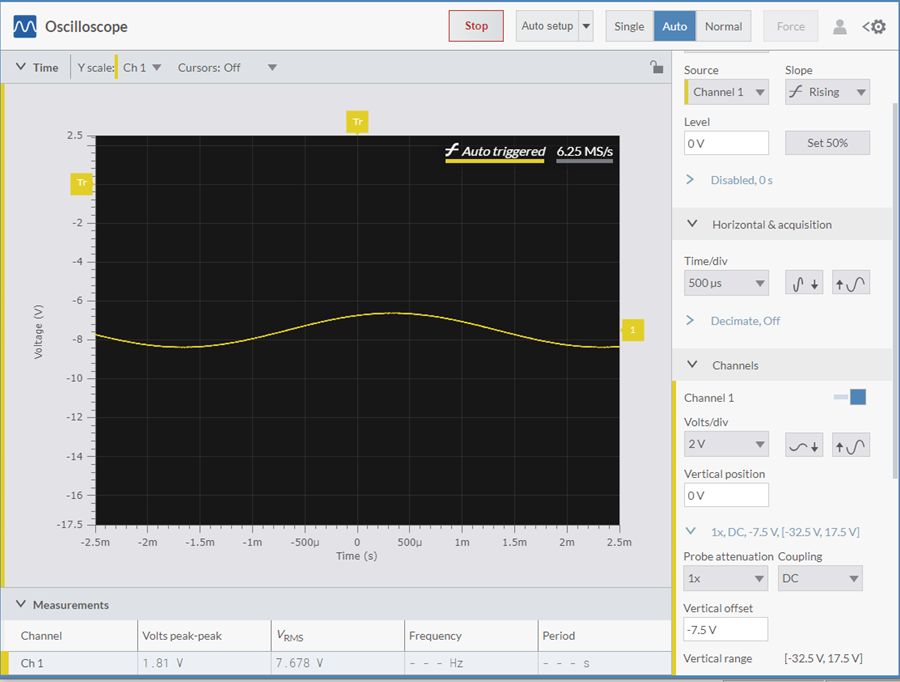

#### Problem 5

You now want to rescale the signal so that it covers more divisions for a more accurate reading. What setting do you need to adjust to increase the top-to-bottom size (Voltage) of your signal?

- Vertical Offset (V)

- Trigger Settings

- Timebase (Time/div)

- Voltage Scale (Volts/div)

- Cursor Settings

Problem_5_Answer = "-" % Select answer from list

#### Problem 6

Should you increase or decrease this setting?

- Increase

- Decrease

Problem_6_Answer = "-" % Select answer from list

The signal is now displayed across the greatest possible number of divisions on the screen as shown below resulting in an accurate amplitude calculation. However, the oscilloscope is still unable to determine the frequency of the signal.

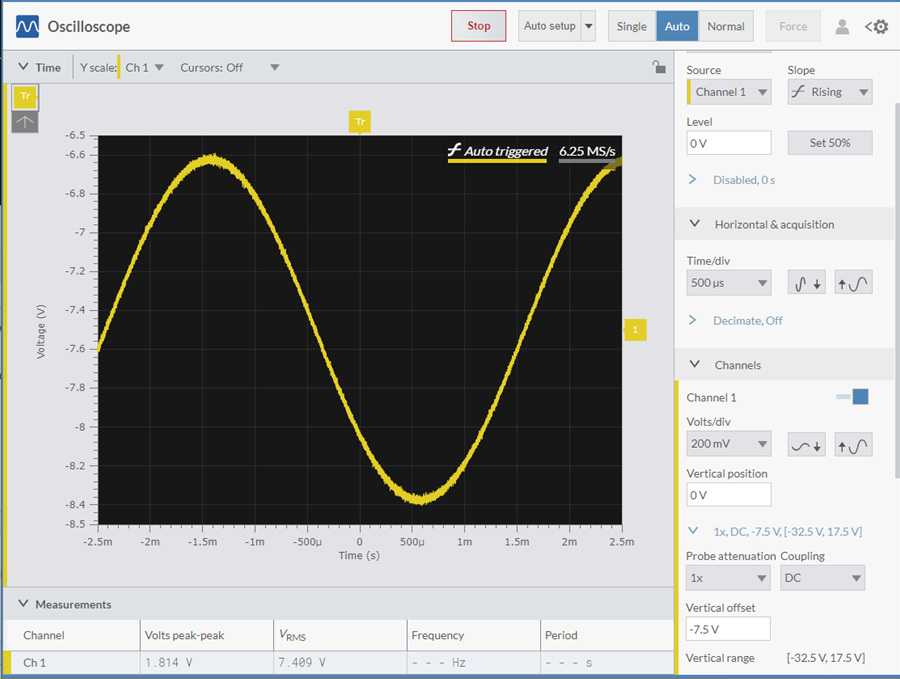

#### Problem 7

What setting do you need to adjust so that there are more cycles on the oscilloscope screen?

- Vertical Offset (V)

- Trigger Settings

- Timebase (Time/div)

- Voltage Scale (Volts/div)

- Cursor Settings

Problem_7_Answer = "-" % Select answer from list

#### Problem 8

Should you increase or decrease this setting?

- Increase

- Decrease

Problem_8_Answer = "-" % Select answer from list

### Edge Trigger

After adjusting the signal accordingly, the amplitude and the frequency are being calculated by the oscilloscope as shown below. However, the signal is moving wildly back and forth on the oscilloscope. You need to set an **edge trigger**, a horizontal line that will intersect the signal (preferably near its midpoint since it is near vertical) and stop it from moving.

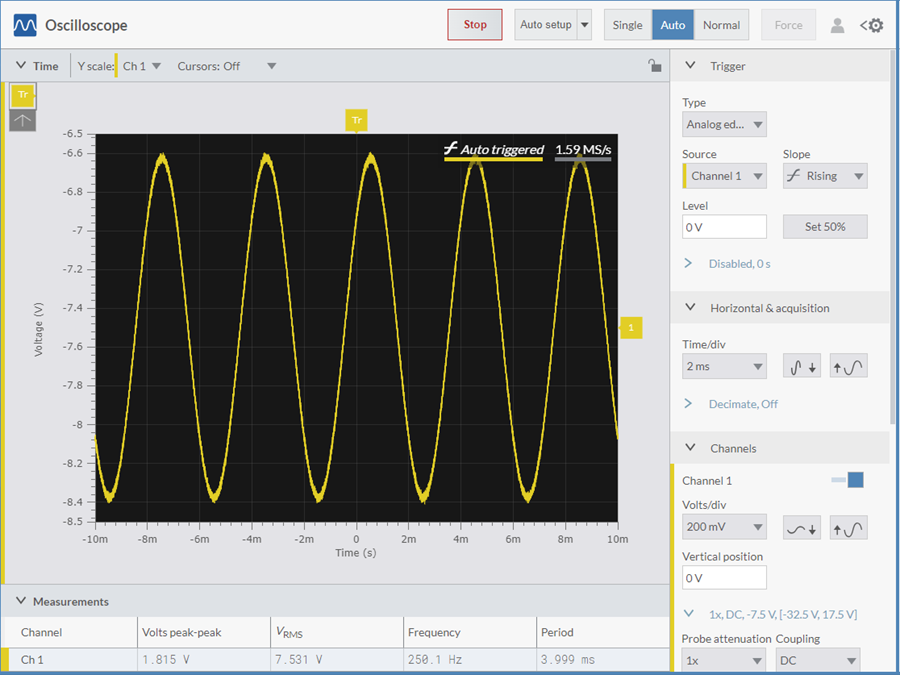

#### Problem 9

What would be an optimal value to set the edge trigger level to based upon the information in the window above? 

Problem_9_Answer = 0 % Edge trigger value in volts

## Signal Conditioning

In lab you will be analyzing the response of a amplifier and low pass filter signal condition system to determine if it meets a clients specifications for a range of input voltages and frequencies. The gain of the amplifier and the range of input voltages which will provide a linear response will be determined experimentally at a set frequency. You will do this by using the built in the function generator and oscilloscope in the ELVIS III to measure the response of the signal condition system to range of inputs. You will then conduct a linear regression analysis in MATLAB to determine the value of the gain (output/input) for the linear range of the responses. The frequency response of the system will then be determined using the built in Bode Analyzer in the ELVIS III.  

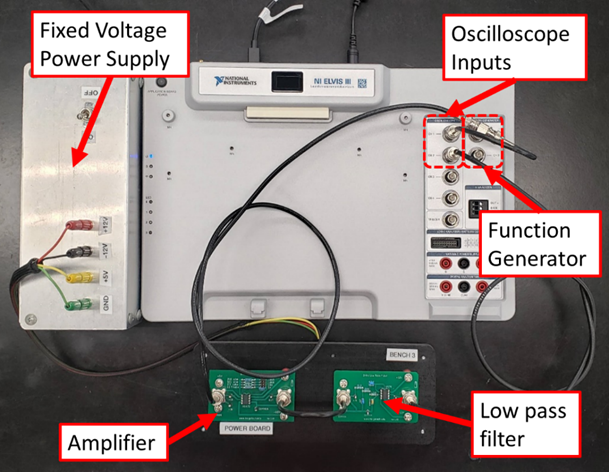

### Amplification

A sample dataset, ***Signal_Conditioning_Gain_Experiment_Data.mat***, can be found in the Homework 1 assignment on Canvas. The code block below will load the data if its is located in the same directory as this MATLAB Live Script. (Running the section will execute the code.)

load( 'Signal_Conditioning_Gain_Experiment_Data.mat' );

% Variable descriptions
input_V; % Input peak-to-peak voltage into signal conditioning circuit
output_V; % Output peak-to-peak voltage out of signal conditioning circuit

The first step in the analysis is to determine the linear range of the signal conditioning circuit and the corresponding input voltage.

#### Problem 10

In the code block below, create a well formatted plot of the output voltage versus the input voltage. 

*(****Note:**** Since this is an experimental dataset, make sure to use markers for the datapoints.)*

% Enter code here

#### Problem 11

What is the range of input voltages that gain (output/input) of the signal conditioning system is constant (linear input/output relationship)? 

*(****Note:**** Clicking on the datapoints in the figure from Problem 10 will create data markers with the values. This is useful for getting quick values, but do not use them for annotations in plots for your reports.)*

lowerRange = 0 % V, lower limit of the linear range
upperRange = 0 % V, upper limit of the linear range

#### Problem 12

What is the gain (output/input) of the signal conditioning system? 

*(Note: Use the fit() function in Matlab to perform the linear regression. Do not guess or use an approximation. We will be using this function extensively later in the class. If you are unfamiliar with it, try using *help fit* or see the example code in the *MATLAB Examples* module on Canvas.) *

*(Note: Try using logical indexing to select the data in the linear range using the answers from Problem 11. Later in the class you will be dealing with large datasets which will make manually selecting data hard.) *

*(Hint: Your answer should be between 3 and 6 V/V.)*

% Enter code here

#### Problem 13

In the code block below, create a well formatted plot of the output voltage versus the input voltage and the trend line for the linear range of the data. Make sure to use markers for the datapoints, a line for the trendline, and include a legend. 

*(****Note:**** You can either add the trendline to the figure from Problem 10 or create a new figure.)*

% Enter code here

### Filtering

The dynamics of the low pass filter and amplifier in the signal conditioning system create additional limits on the useful range of signal frequencies for which amplification if possible. The ELVIS III can conduct a frequency analysis to determine the response of the system versus input frequency using the Bode Analyzer. A sample set, ***Signal_Conditioning_Frequency_Experiment_Data.mat***, can be found in the Homework 1 assignment on Canvas. The code block below will load the data if its is located in the same directory as this MATLAB Live Script. (Running the section will execute the code.)

load( 'Signal_Conditioning_Frequency_Experiment_Data.mat' );

% Variable descriptions
frequency_Hz; % Hz, input frequency into signal conditioning circuit
gain_V_V; % V/V, gain of signal conditioning circuit
phase_deg; % deg, phase shift of signal conditioning circuit

#### Problem 14

Create a well formatted Bode plot of the amplifier system gain (in **decibels**) and the phase lag (in degrees). 

*(****Note: ****A subplot is a good way in MATLAB to create the typical Body plot layout. The Amplifiers Resource in the Block 1 Module on Canvas has an example of a Bode Plot.) *

*(****Note:**** Since this is an experimental dataset, make sure to use markers for the datapoints.)*

% Enter code here

#### Problem 15

What is the cutoff frequency (in Hertz) of the amplifier system?

*(****Note: ****Use the frequency of data point which first meets the criteria which can be found in the Amplifiers Resource in the Block 1 Module on Canvas.)*

*(****Hint: ****It should be between 1500 and 2500 Hz.)*

% Enter code here